syms s
l = 0.04*cos(pi/4);
m = 0.031;
roll_o = 0;
pitch_o = 0;
yaw_o = 0;
u_1= 0.3

u_1 = 0.3000

%syms ix iy iz
ix = 1.1329*10^-5;
iy = 1.1329*10^-5;
iz = 2.0289*10^-5;

A = [0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0;
     0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0;
     0, 0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0;
     0, 0, 0, 0, 0, 0, ((yaw_o-pitch_o*roll_o)*u_1)/m,u_1/m,((roll_o-yaw_o*pitch_o)*u_1)/m,0,0,0;
     0, 0, 0, 0, 0, 0, ((-1-yaw_o*pitch_o*roll_o)*u_1)/m,(yaw_o*u_1)/m,((yaw_o*roll_o+pitch_o)*u_1)/m,0,0,0;
     0, 0, 0, 0, 0, 0, -(roll_o*u_1)/m, -(pitch_o*u_1)/m,0,0,0,0;
     0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 0;
     0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0;
     0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1;
     0, 0, 0, 0, 0, 0, 0, (yaw_o*(iz-iy))/ix,(pitch_o*(iz-iy)/ix),0,0,0;
     0, 0, 0, 0, 0, 0, (yaw_o*(ix-iz))/iy,0,(roll_o*(ix-iz))/iy, 0, 0, 0;
     0, 0, 0, 0, 0, 0, (pitch_o*(iy-ix)/iz),(roll_o*(iy-ix)/iz), 0, 0, 0, 0]

A =          0         0         0    1.0000         0         0         0         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0
         0         0         0         0         0         0         0    9.6774         0         0         0         0
         0         0         0         0         0         0   -9.6774         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0    1.0000         0         0
         0         0         0         0         0         0         0         0         0         0    1.0000         0
         0         0        



B_full = [0, 0, 0, 0;
     0, 0, 0, 0;
     0, 0, 0, 0;
     (sin(yaw_o)*sin(roll_o)+cos(yaw_o)*sin(pitch_o)*cos(roll_o))/m, 0, 0, 0;
     (-cos(yaw_o)*sin(roll_o)+sin(yaw_o)*sin(pitch_o)*cos(roll_o))/m, 0, 0, 0;
     (cos(pitch_o)*cos(roll_o))/m, 0, 0, 0;
     0, 0, 0, 0;
     0, 0, 0, 0;
     0, 0, 0, 0;
     0, l/ix, 0, 0;
     0, 0, l/iy, 0;
     0, 0, 0, l/iz;]

B_full = 1.0e+03 *

         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
    0.0323         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0    2.4966         0         0



B = [0, 0, 0, 0;
     0, 0, 0, 0;
     0, 0, 0, 0;
     (yaw_o*roll_o+pitch_o)/m, 0, 0, 0;
     (-roll_o+yaw_o*pitch_o)/m, 0, 0, 0;
     1/m, 0, 0, 0;
     0, 0, 0, 0;
     0, 0, 0, 0;
     0, 0, 0, 0;
     0, l/ix, 0, 0;
     0, 0, l/iy, 0;
     0, 0, 0, l/iz;]

B = 1.0e+03 *

         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
    0.0323         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0    2.4966         0         0





test=svd(A)

test =     9.6774
    9.6774
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
         0
         0




G = ss(A,B,eye(12),0)

G =
 
  A = 
            x1      x2      x3      x4      x5      x6      x7      x8      x9     x10     x11     x12
   x1        0       0       0       1       0       0       0       0       0       0       0       0
   x2        0       0       0       0       1       0       0       0       0       0       0       0
   x3        0       0       0       0       0       1       0       0       0       0       0       0
   x4        0       0       0       0       0       0       0   9.677       0       0       0       0
   x5        0       0       0       0       0       0  -9.677       0       0       0       0       0
   x6        0       0       0       0       0       0       0       0       0       0       0       0
   x7        0       0       0       0       0       0       0       0       0       1       0       0
   x8        0       0       0       0       0       0       0       0       0       0       1       0
   x9        0       0       0       0       0       0      

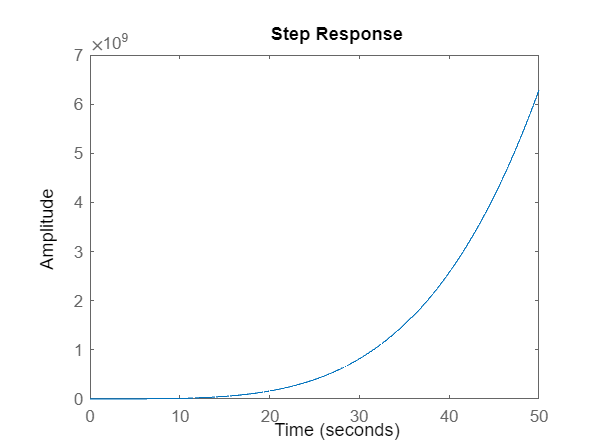

step(G(1,3))

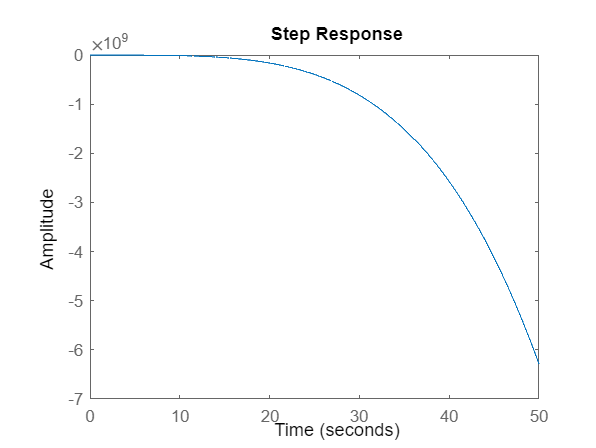

step(G(2,2))

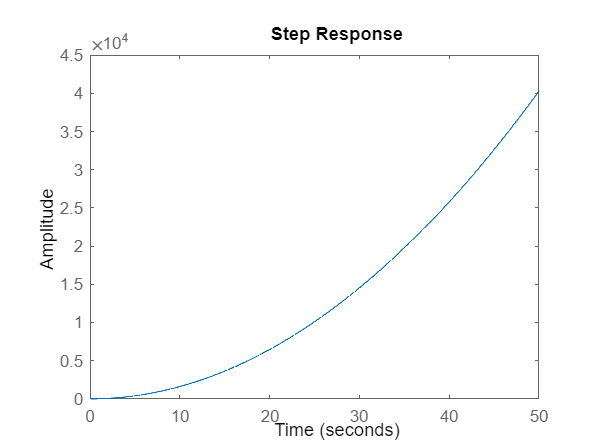

step(G(3,1 ))

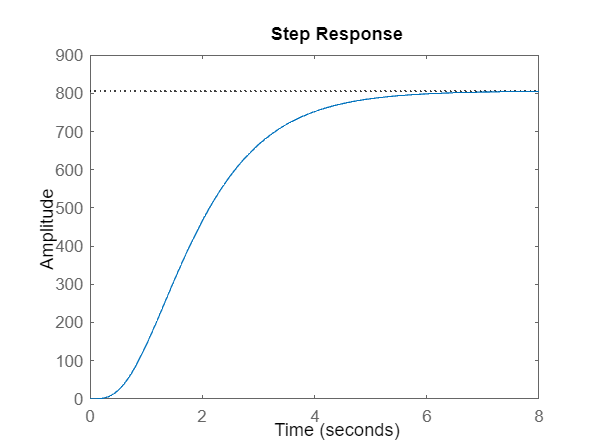


p = [-1,-2,-1,-1,-1,-3,-4,-5,-3,-2,-3,-2];

K = place(A,B,p);

Acl = A-B*K;
syscl = ss(Acl,B,eye(12),0);
Pcl = pole(syscl);

figure(1)
step(syscl(1,3))

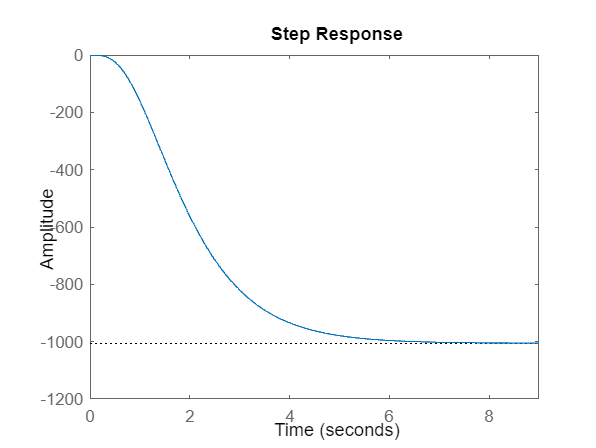

step(syscl(2,2))

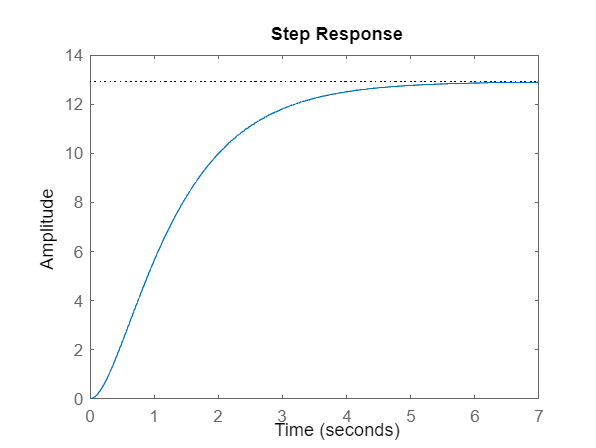

step(syscl(3,1))

s =tf('s')

s =
 
  s
 
Continuous-time transfer function.




G_x = 17084.33*sqrt(2)/s^4;
G_y = -17084.33*sqrt(2)/s^4;
G_z = 32.258064/s^2;




f = 8.16*10^-6/(0.136*s+1)

f =
 
   8.16e-06
  -----------
  0.136 s + 1
 
Continuous-time transfer function.




test_x = f*G_x

test_x =
 
      0.1972
  ---------------
  0.136 s^5 + s^4
 
Continuous-time transfer function.



test_y = f*G_y

test_y =
 
      -0.1972
  ---------------
  0.136 s^5 + s^4
 
Continuous-time transfer function.



test_z = f*G_z

test_z =
 
     0.0002632
  ---------------
  0.136 s^3 + s^2
 
Continuous-time transfer function.



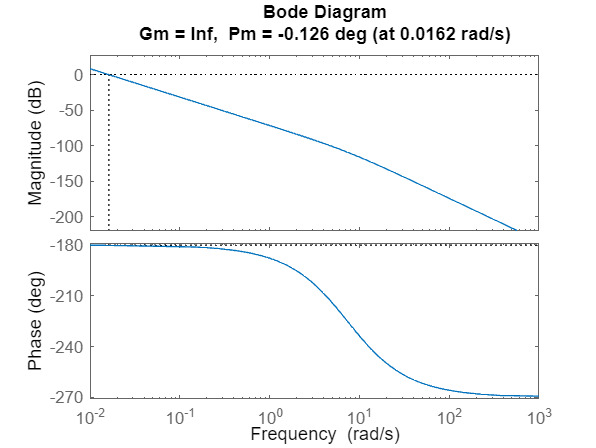


margin(test_z)



sys = ss(test_x)

sys =
 
  A = 
           x1      x2      x3      x4      x5
   x1  -7.353       0       0       0       0
   x2       1       0       0       0       0
   x3       0       1       0       0       0
   x4       0       0       1       0       0
   x5       0       0       0       1       0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
   x4   0
   x5   0
 
  C = 
         x1    x2    x3    x4    x5
   y1     0     0     0     0  1.45
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.




pole(sys)

ans =          0
         0
         0
         0
   -7.3529


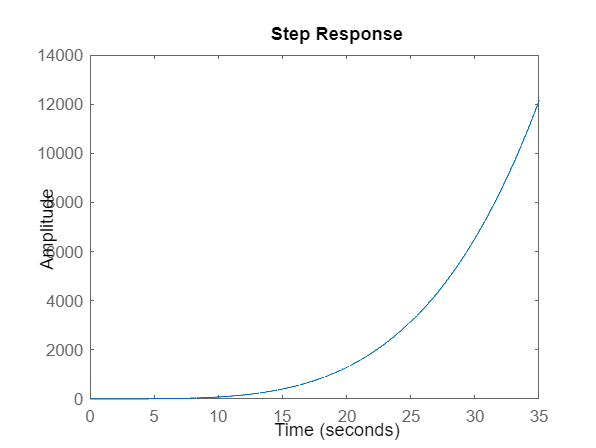


step(sys)

new_poles = [-1,-2,-3,-4,-7]

new_poles =     -1    -2    -3    -4    -7



rank(sys.B)

ans = 1


k = place(sys.A,sys.B,new_poles)

k =     9.6471  105.0000  295.0000  374.0000  168.0000



acl = sys.A-sys.B*k;
syscl = ss(acl,sys.B,eye(5),0)

syscl =
 
  A = 
         x1    x2    x3    x4    x5
   x1   -17  -105  -295  -374  -168
   x2     1     0     0     0     0
   x3     0     1     0     0     0
   x4     0     0     1     0     0
   x5     0     0     0     1     0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
   x4   0
   x5   0
 
  C = 
       x1  x2  x3  x4  x5
   y1   1   0   0   0   0
   y2   0   1   0   0   0
   y3   0   0   1   0   0
   y4   0   0   0   1   0
   y5   0   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
   y5   0
 
Continuous-time state-space model.



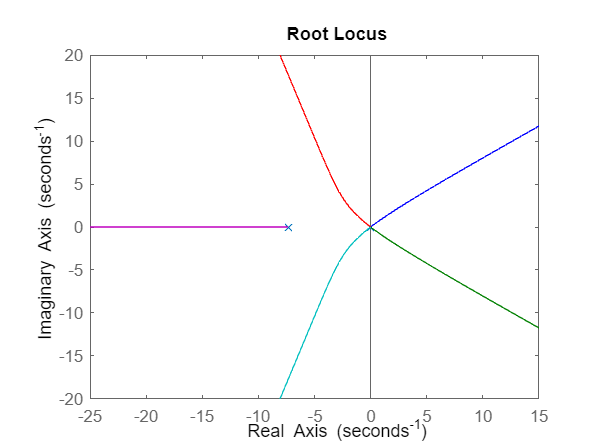


rlocus(sys)

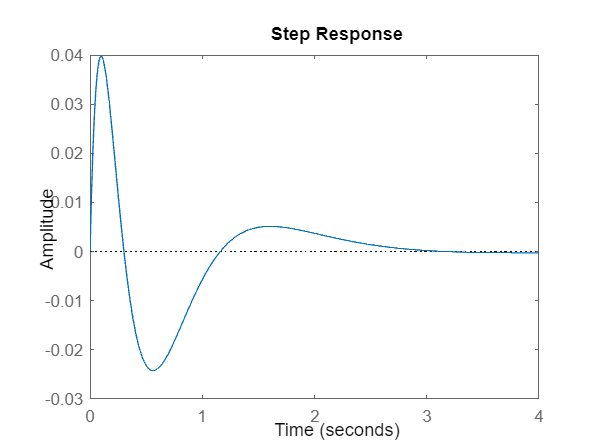


figure(1)
step(syscl(1))

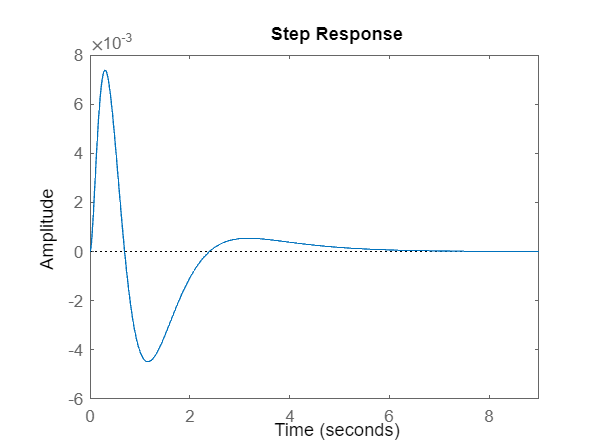

step(syscl(2))

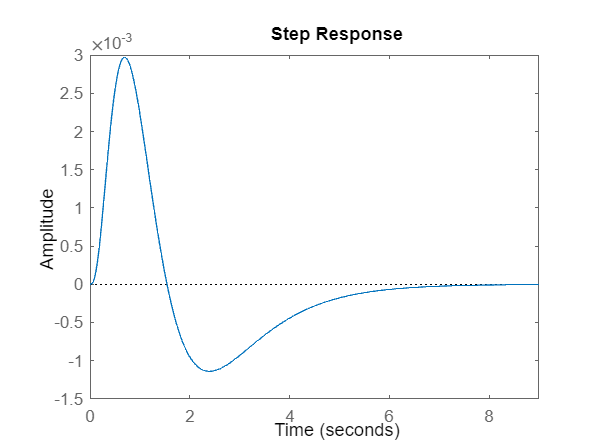

step(syscl(3))

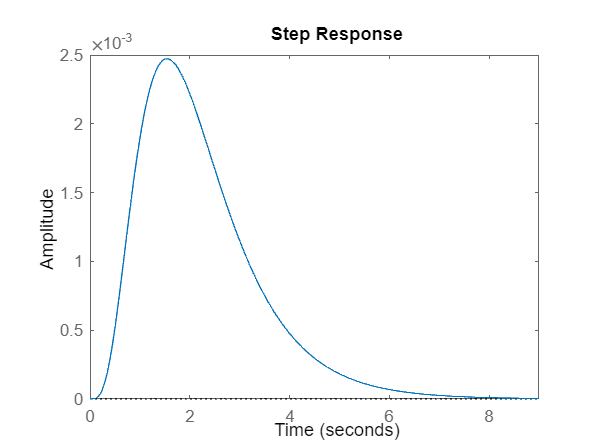

step(syscl(4))

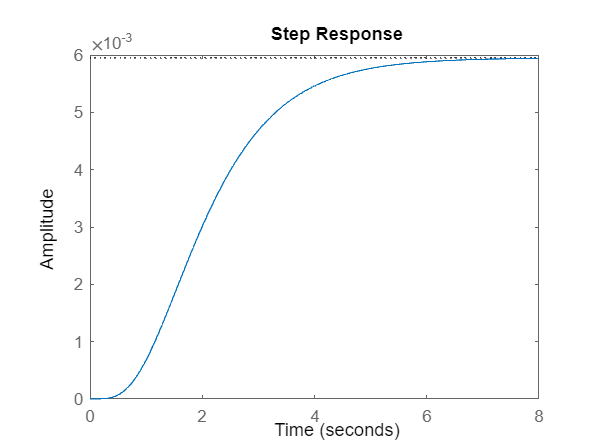

step(syscl(5))




%margin(G_z)
%margin(test_z)

X = pidtune(test_x,'PID')

X =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 1.07e+04, Ki = 1.22e+03, Kd = 2.33e+04
 
Continuous-time PID controller in parallel form.



Y = pidtune(test_y,'PID')

Y =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = -1.07e+04, Ki = -1.22e+03, Kd = -2.33e+04
 
Continuous-time PID controller in parallel form.



[Z,info] = pidtune(G_z,'PID',100)

Z =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 70.8, Ki = 410, Kd = 3.06
 
Continuous-time PID controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 100
           PhaseMargin: 76.7968


full = feedback(Z*G_z,1)

full =
 
     98.68 s^2 + 2284 s + 1.322e04
  -----------------------------------
  s^3 + 98.68 s^2 + 2284 s + 1.322e04
 
Continuous-time transfer function.



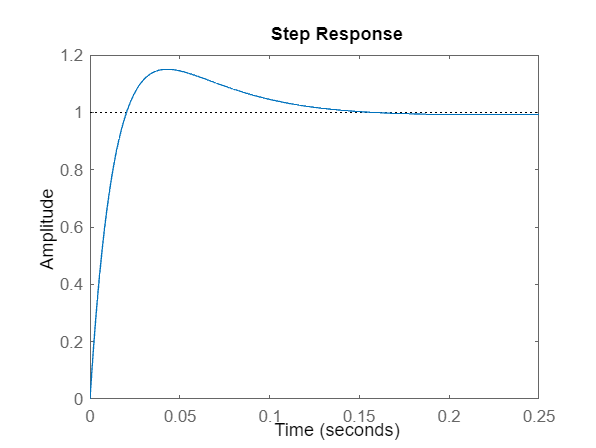


step(full)